D = readtable("normalizedData.txt");
Inputs = D{:,2:5};
Outputs = D{:,6:end};

% Convert data to time series
X = tonndata(Inputs, false, false);
T = tonndata(Outputs, false, false);

% Choose a Training Function
trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation.

% Create a Nonlinear Autoregressive Network with External Input
inputDelays = 1:2;
feedbackDelays = 1:2;
hiddenLayerSize = 10;
net = narxnet(inputDelays, feedbackDelays, hiddenLayerSize, 'open', trainFcn);

% Pre/Post-Processing Functions
net.inputs{1}.processFcns = {'removeconstantrows','mapminmax'};
net.inputs{2}.processFcns = {'removeconstantrows','mapminmax'};

% Prepare the Data for Training and Simulation
[x, xi, ai, t] = preparets(net, X, {}, T);

% Setup Division of Data for Training, Validation, Testing
net.divideFcn = 'divideind';  
net.divideMode = 'time';

%Training

sIv1 = datetime('01-Sep-2023 00:15:00');
eIv1 = datetime('15-Sep-2023 00:00:00');
sIv2 = datetime('29-Sep-2023 00:15:00');
eIv2 = datetime('13-Oct-2023 00:00:00');
sIv3 = datetime('27-Oct-2023 00:15:00');
eIv3 = datetime('17-Nov-2023 09:15:00');
sIv4 = datetime('15-Dec-2023 00:15:00');
eIv4 = datetime('29-Dec-2023 00:00:00');
sIv5 = datetime('12-Jan-2024 00:15:00');
eIv5 = datetime('26-Jan-2024 00:00:00');
sIv6 = datetime('09-Feb-2024 00:15:00');
eIv6 = datetime('21-Feb-2024 11:45:00');
sIv7 = datetime('08-Mar-2024 00:15:00');
eIv7 = datetime('22-Mar-2024 00:00:00');
sIv8 = datetime('05-Apr-2024 00:15:00');
eIv8 = datetime('19-Apr-2024 00:00:00');

net.divideParam.trainInd = [find(D.timestamps >= sIv1 & D.timestamps <= eIv1) 
                            find(D.timestamps >= sIv2 & D.timestamps <= eIv2)
                            find(D.timestamps >= sIv3 & D.timestamps <= eIv3)
                            find(D.timestamps >= sIv4 & D.timestamps <= eIv4)
                            find(D.timestamps >= sIv5 & D.timestamps <= eIv5)
                            find(D.timestamps >= sIv6 & D.timestamps <= eIv6)
                            find(D.timestamps >= sIv7 & D.timestamps <= eIv7)
                            find(D.timestamps >= sIv8 & D.timestamps <= eIv8)]


net =

    Neural Network
 
              name: 'NARX Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 2
         numLayers: 2
        numOutputs: 1
    numInputDelays: 2
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 10
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConnect


%Validierung

sIv1 = datetime('15-Sep-2023 00:15:00');
eIv1 = datetime('22-Sep-2023 00:00:00');
sIv2 = datetime('13-Oct-2023 00:15:00');
eIv2 = datetime('20-Oct-2023 00:00:00');
sIv3 = datetime('01-Dec-2023 12:15:00');
eIv3 = datetime('08-Dec-2023 00:00:00');
sIv4 = datetime('29-Dec-2023 00:15:00');
eIv4 = datetime('05-Jan-2024 00:00:00');
sIv5 = datetime('26-Jan-2024 00:15:00');
eIv5 = datetime('02-Feb-2024 00:00:00');
sIv6 = datetime('23-Feb-2024 12:15:00');
eIv6 = datetime('28-Feb-2024 23:45:00');
sIv7 = datetime('22-Mar-2024 00:15:00');
eIv7 = datetime('29-Mar-2024 00:00:00');
sIv8 = datetime('19-Apr-2024 00:15:00');
eIv8 = datetime('26-Apr-2024 00:00:00');

net.divideParam.valInd =   [find(D.timestamps >= sIv1 & D.timestamps <= eIv1) 
                            find(D.timestamps >= sIv2 & D.timestamps <= eIv2)
                            find(D.timestamps >= sIv3 & D.timestamps <= eIv3)
                            find(D.timestamps >= sIv4 & D.timestamps <= eIv4)
                            find(D.timestamps >= sIv5 & D.timestamps <= eIv5)
                            find(D.timestamps >= sIv6 & D.timestamps <= eIv6)
                            find(D.timestamps >= sIv7 & D.timestamps <= eIv7)
                            find(D.timestamps >= sIv8 & D.timestamps <= eIv8)]


net =

    Neural Network
 
              name: 'NARX Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 2
         numLayers: 2
        numOutputs: 1
    numInputDelays: 2
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 10
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConnect


%Test

sIv1 = datetime('22-Sep-2023 00:15:00');
eIv1 = datetime('29-Sep-2023 00:00:00');
sIv2 = datetime('20-Oct-2023 00:15:00');
eIv2 = datetime('27-Oct-2023 00:00:00');
sIv3 = datetime('08-Dec-2023 00:15:00');
eIv3 = datetime('15-Dec-2023 00:00:00');
sIv4 = datetime('05-Jan-2024 00:15:00');
eIv4 = datetime('12-Jan-2024 00:00:00');
sIv5 = datetime('02-Feb-2024 00:15:00');
eIv5 = datetime('09-Feb-2024 00:00:00');
sIv6 = datetime('01-Mar-2024 00:15:00');
eIv6 = datetime('08-Mar-2024 00:00:00');
sIv7 = datetime('29-Mar-2024 00:15:00');
eIv7 = datetime('05-Apr-2024 00:00:00');
sIv8 = datetime('26-Apr-2024 00:15:00');
eIv8 = datetime('29-Apr-2024 23:45:00');

net.divideParam.testInd =  [find(D.timestamps >= sIv1 & D.timestamps <= eIv1) 
                            find(D.timestamps >= sIv2 & D.timestamps <= eIv2)
                            find(D.timestamps >= sIv3 & D.timestamps <= eIv3)
                            find(D.timestamps >= sIv4 & D.timestamps <= eIv4)
                            find(D.timestamps >= sIv5 & D.timestamps <= eIv5)
                            find(D.timestamps >= sIv6 & D.timestamps <= eIv6)
                            find(D.timestamps >= sIv7 & D.timestamps <= eIv7)
                            find(D.timestamps >= sIv8 & D.timestamps <= eIv8)]


net =

    Neural Network
 
              name: 'NARX Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 2
         numLayers: 2
        numOutputs: 1
    numInputDelays: 2
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 10
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConnect

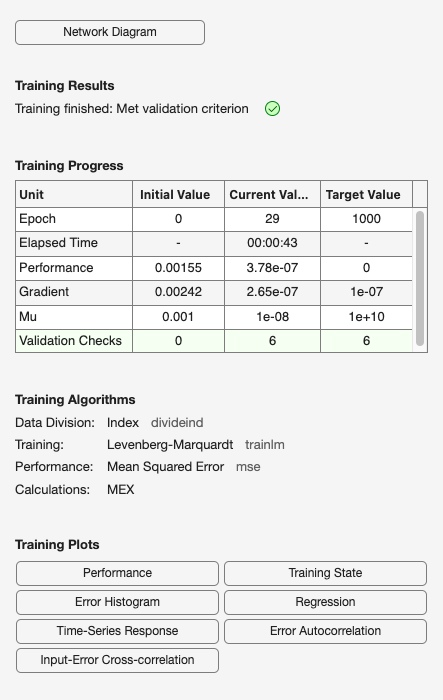



% Choose a Performance Function
net.performFcn = 'mse';

% Train the Network
[net, tr] = train(net, x, t, xi, ai);


% Test the Network
y = net(x, xi, ai);
e = gsubtract(t, y);
performance = perform(net, t, y);

% Closed-Loop Network Configuration
netc = closeloop(net);
netc.name = [net.name ' - Closed Loop 96 Step Prediction'];


% Multi-step Prediction (96 Steps)
numTimesteps = size(x, 2);
knownOutputTimesteps = 1:(numTimesteps-96);
predictOutputTimesteps = (numTimesteps-95):numTimesteps;

% Open-loop simulation with known outputs
X1 = X(:, knownOutputTimesteps);
T1 = T(:, knownOutputTimesteps);
[x1, xio, aio] = preparets(net, X1, {}, T1);
[y1, xfo, afo] = net(x1, xio, aio);  % Simulate open-loop

% Closed-loop simulation for 96 steps ahead
x2 = X(:, predictOutputTimesteps);  % External inputs
[netc, xic, aic] = closeloop(net, xfo, afo);  % Switch to closed-loop
[y2, xfc, afc] = netc(x2, xic, aic);  % Simulate closed-loop

% Performance evaluation
multiStepPerformance = perform(netc, T(:, predictOutputTimesteps), y2);

% Display results
disp("Multi-step Prediction Performance:");

Multi-step Prediction Performance:


disp(multiStepPerformance);

   5.4056e-05



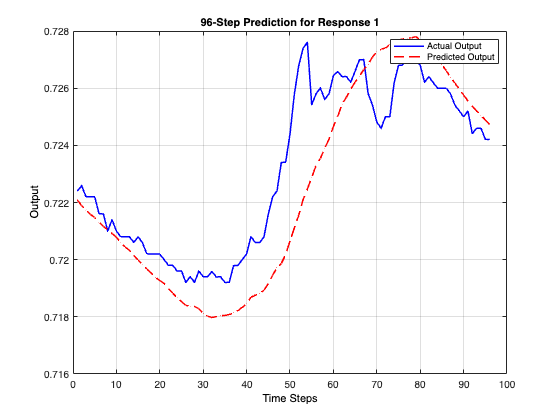

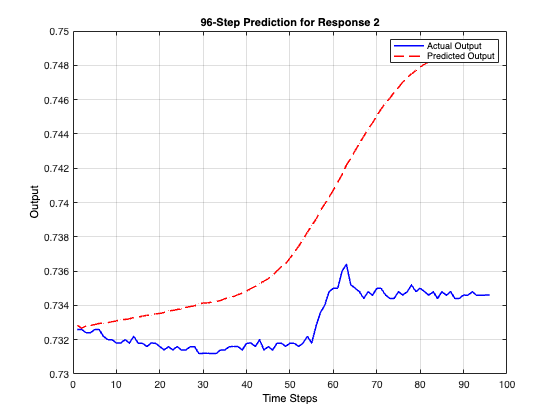

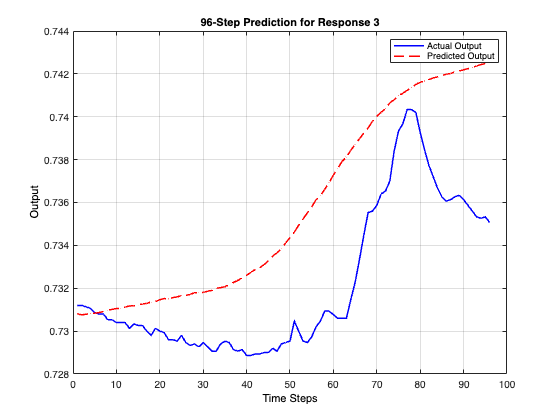

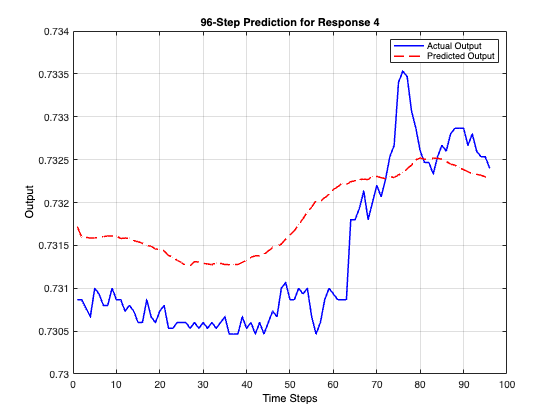

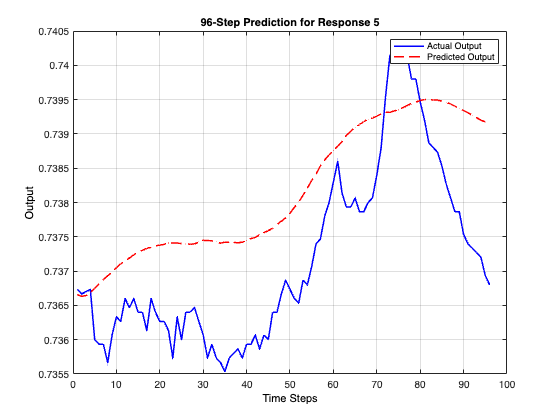

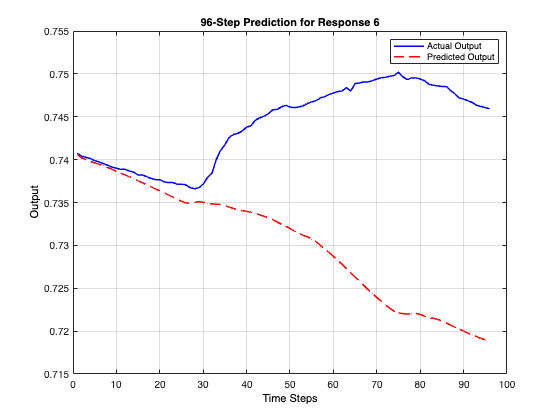

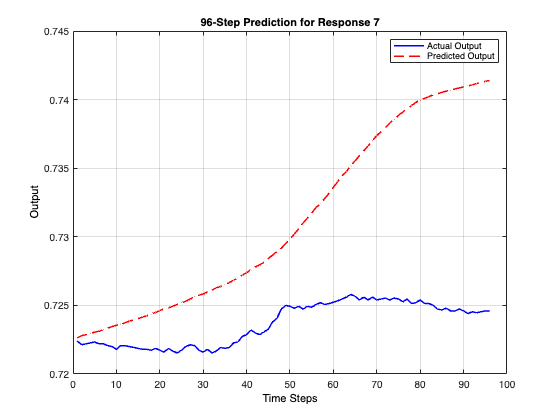

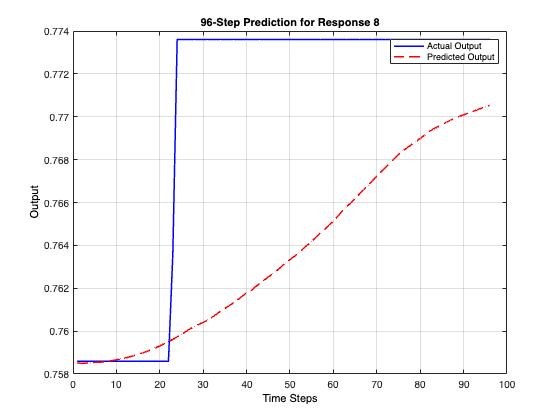


% Determine the number of responses
numResponses = size(Outputs, 2);

% Plot each response separately
for i = 1:numResponses
    figure;
    
    % Extract actual outputs for the current response
    actualOutput = cell2mat(cellfun(@(c) c(i), T(predictOutputTimesteps), 'UniformOutput', false));
    % Extract predicted outputs for the current response
    predictedOutput = cell2mat(cellfun(@(c) c(i), y2, 'UniformOutput', false));

    % Plot actual and predicted outputs
    plot(actualOutput, 'b', 'LineWidth', 1.5); hold on;
    plot(predictedOutput, 'r--', 'LineWidth', 1.5);

    % Customize the plot
    legend({'Actual Output', 'Predicted Output'}, 'TextColor', 'black');
    title(['96-Step Prediction for Response ', num2str(i)], 'Color', 'black');
    xlabel('Time Steps', 'Color', 'black');
    ylabel('Output', 'Color', 'black');
    %set(gca, 'XColor', 'white', 'YColor', 'white', 'Color', 'black'); % Dark mode styling
    grid on;
end



% Save the closed-loop network
save("netclosed96", "netc");